% AAE666 HW2 EXERCISE2 MATLAB SCRIPT    
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2021-Spring\AAE666\matlab\hw2';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

Amat = @(ye) [0, 1; -cos(ye), 0]; 

% ye = (2m)pi
ye = 0;
A = Amat(ye);
[v, lambda] = eig(A);

% ye = (2m+1)pi
ye = pi;
A = Amat(ye);
[v, lambda] = eig(A);

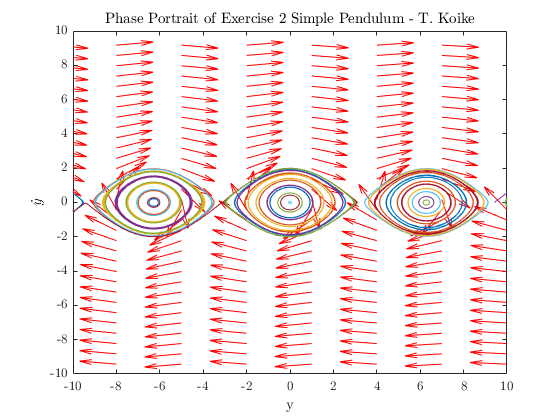

% Phase Portrait
f = @(t,x) [x(2);-sin(x(1))];
fig = vectfield(f,-20:3:20,-3*pi:0.6:3*pi);
hold on
for yi=-4*pi:0.5:4*pi
  [ts,ys] = ode45(f,[0,100],[yi;0]);
  plot(ys(:,1),ys(:,2))
end
hold off
title('Phase Portrait of Exercise 2 Simple Pendulum - T. Koike')
xlabel('y')
xlim([-10, 10])
ylabel('$\dot{y}$')
saveas(fig, fullfile(fdir, "ex2-phase-portrait.png"));

function fig = vectfield(func,y1val,y2val,t)
    if nargin==3
      t=0;
    end
    n1=length(y1val);
    n2=length(y2val);
    yp1=zeros(n2,n1);
    yp2=zeros(n2,n1);
    for i=1:n1
      for j=1:n2
        ypv = feval(func,t,[y1val(i);y2val(j)]);
        yp1(j,i) = ypv(1);
        yp2(j,i) = ypv(2);
      end
    end
    len=sqrt(yp1.^2+yp2.^2);
    fig = quiver(y1val,y2val,yp1./len,yp2./len,.6,'r');
end